clc
clear

mf = 2.02;

mf = 2.0200

mb = 8.1;

mb = 8.1000

hf = 0.48;

hf = 0.4800

hb = 0.42;

hb = 0.4200

Ib=1.43;

Ib = 1.4300

Ip=0.0088;

Ip = 0.0088

Ir= 0.0224;

Ir = 0.0224

w=469;

w = 469

L=0.000119;

L = 1.1900e-04

R=0.61;

R = 0.6100

Bm=0.003;

Bm = 0.0030

Km=0.0259;

Km = 0.0259

Ke=0.0027;

Ke = 0.0027

g=9.81;

g = 9.8100

A=[ 0 1 0 0;
    g*(mb*hb+mf*hf)/(mb*hb^2+mf*hf^2+Ib + Ir) 0 Ip*w/(mb*hb^2+mf*hf^2+Ib + Ir) 0;
    0 -Ip*w/Ir -Bm/Ir 65*Km/Ir;
    0 0 -Ke/L -R/L];
B = [0;0;0;1/L];
C = [1 0 0 0];
D = 0;
system = ss(A,B,C,D);


system =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2    12.81        0    1.233        0
   x3        0   -184.3  -0.1339    75.16
   x4        0        0   -22.69    -5126
 
  B = 
         u1
   x1     0
   x2     0
   x3     0
   x4  8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



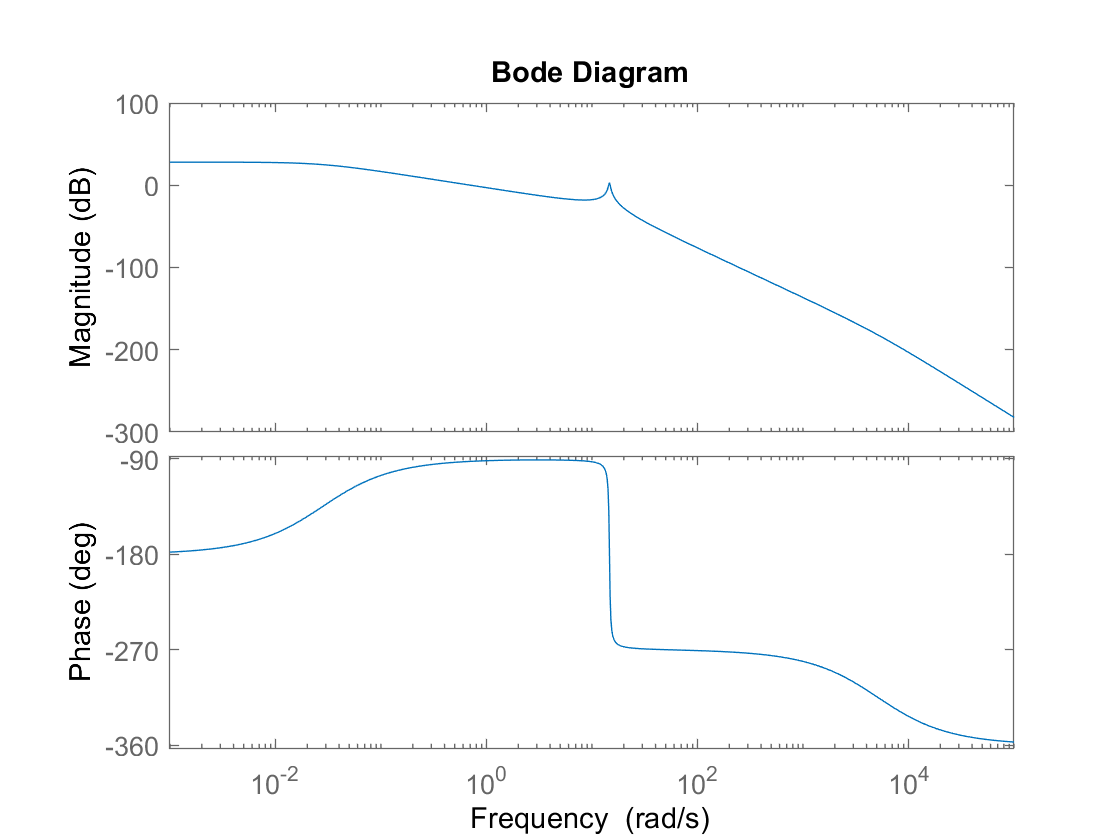

bode(system);

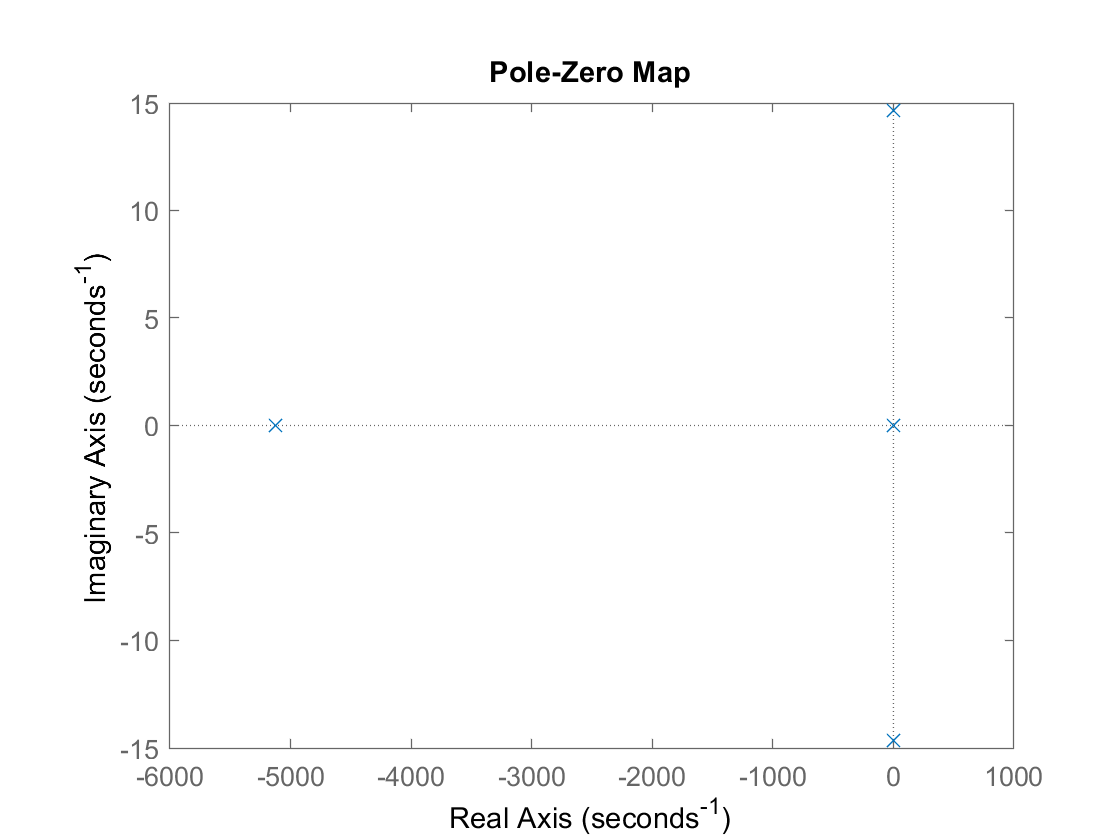

pzmap(system);

systeem= ss(A,B,C,D); % uncompensated systeemtem (no controller)


systeem =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2    12.81        0    1.233        0
   x3        0   -184.3  -0.1339    75.16
   x4        0        0   -22.69    -5126
 
  B = 
         u1
   x1     0
   x2     0
   x3     0
   x4  8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


T =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


A2 = 	1.0e+03 *

         0    0.0010         0         0
    0.0128         0    0.0012         0
         0   -0.1846   -0.0001    0.0750
         0         0   -0.0227   -5.1260


B2 =            0
           0
           0
        8403


C2 =      1     0     0     0


D2 = 0


SYSTEEM =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2   12.82       0   1.238       0
   x3       0  -184.6  -0.133      75
   x4       0       0  -22.69   -5126
 
  B = 
         u1
   x1     0
   x2     0
   x3     0
   x4  8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



num = 	1.0e+05 *

         0         0         0         0    7.8022


den = 	1.0e+06 *

    0.0000    0.0051    0.0026    1.1058   -0.0306



tfunction =
 
                      7.802e05
  -------------------------------------------------
  s^4 + 5126 s^3 + 2599 s^2 + 1.106e06 s - 3.056e04
 
Continuous-time transfer function.



num1 =     0.0200   25.0000


den1 = 1

load PIDFcontroller.mat;
PIDFController


PIDFController =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 3.05, Ki = 0.0511, Kd = -0.882, Tf = 0.305
 
Continuous-time PIDF controller in parallel form.




%PDcontroller =tf(num1, den1)

compensatedsys=PIDFController*tfunction


compensatedsys =
 
                   1.276e05 s^2 + 7.849e06 s + 1.308e05
  -----------------------------------------------------------------------
  s^6 + 5129 s^5 + 1.94e04 s^4 + 1.114e06 s^3 + 3.593e06 s^2 - 1.001e05 s
 
Continuous-time transfer function.




fb =feedback(compensatedsys,1)


fb =
 
                         1.276e05 s^2 + 7.849e06 s + 1.308e05
  ----------------------------------------------------------------------------------
  s^6 + 5129 s^5 + 1.94e04 s^4 + 1.114e06 s^3 + 3.721e06 s^2 + 7.748e06 s + 1.308e05
 
Continuous-time transfer function.




u= zeros(1,10000);
t = [0:1:9999]./100

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u(1:1000)= 1

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


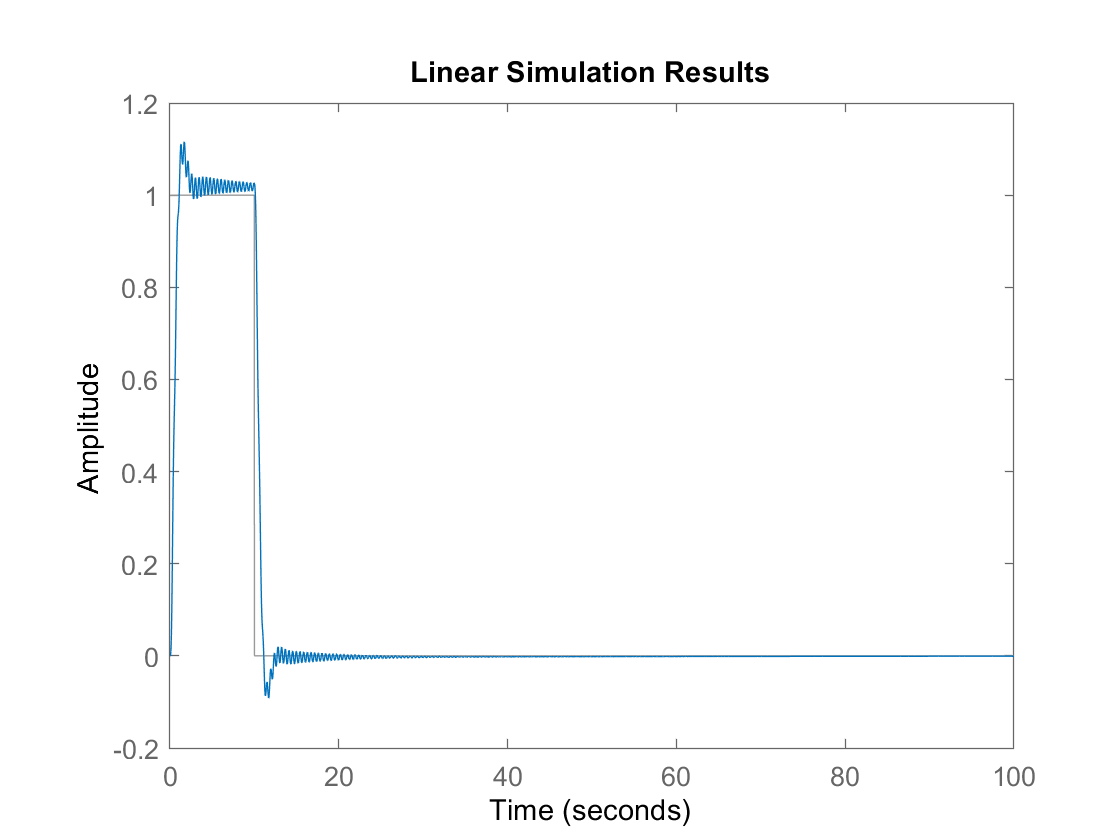

lsim(fb,u,t)